# **HW Set 7 - RBE 502**

clc; clear all;
syms m1 m2 l1 l2 q1 q2 q1dot q2dot g e1 e2 e3 e4 qd1 qd2

x = [q1; q2; q1dot; q2dot;]

$$x = \left(\begin{array}{c} q_{1}\\ q_{2}\\ \mathrm{q1dot}\\ \mathrm{q2dot} \end{array}\right)$$

xd = [qd1; qd2; 0; 0;]

$$xd = \left(\begin{array}{c} {\mathrm{qd}}_{1}\\ {\mathrm{qd}}_{2}\\ 0\\ 0 \end{array}\right)$$

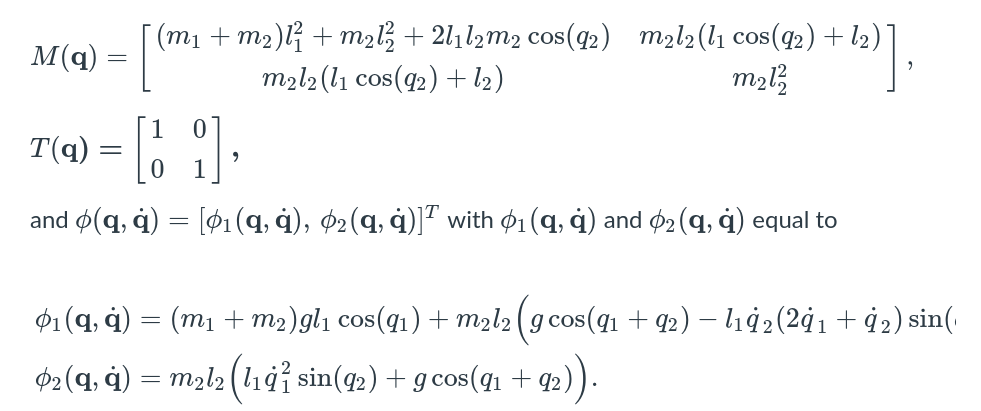

% M = [
%         (m1+m2)*l1^2 + m2*l2^2 + 2*l1*l2*m2*cos(q2)     m2*l2*(l1*cos(q2) + l2);
%         m2*l2*(l1*cos(q2)+l2)                           m2*l2^2
% 
%     ]
T = [1  0;  0   1]

T =      1     0
     0     1


 
phi1 = (m1+m2)*g*l1*cos(q1) + m2*l2*(g*cos(q1+q2)-l1*q2dot*(2*q1dot+q2dot)*sin(q2))

$$phi1 = l_{2}\,m_{2}\,\left(g\,\cos\left(q_{1}+q_{2}\right)-l_{1}\,\mathrm{q2dot}\,\sin\left(q_{2}\right)\,\left(2\,\mathrm{q1dot}+\mathrm{q2dot}\right)\right)+g\,l_{1}\,\cos\left(q_{1}\right)\,\left(m_{1}+m_{2}\right)$$

phi2 = m2*l2*(l1*q1dot^2*sin(q2)+g*cos(q1+q2))

$$phi2 = l_{2}\,m_{2}\,\left(l_{1}\,\sin\left(q_{2}\right)\,{\mathrm{q1dot}}^{2}+g\,\cos\left(q_{1}+q_{2}\right)\right)$$


% phi = [phi1;    phi2;]

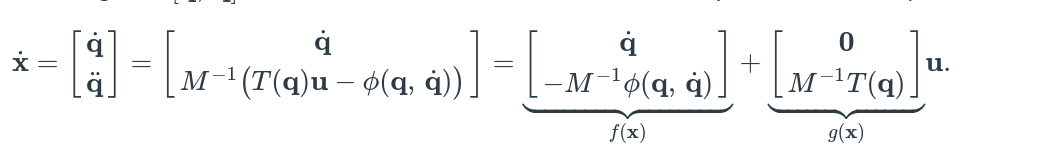

syms m1 m2 l1 l2 q1 q2 q1dot q2dot g e1 e2 e3 e4 qd1 qd2
symspecs = struct("m1", m1, "m2", m2, "g", g, "l1", l1, "l2", l2);

f = @(x, specs) [
    % Qdot in the state is a 2x1 of q1dot and q2dot, which are in
    % the bottom half of the state.
    x(3);
    x(4);
    % Then we place in our M-1*phi(q, qdot) which results in two equations
    -M(x,specs)^-1*phi(x, specs)
]

f = function_handle with value:
    @(x,specs)[x(3);x(4);-M(x,specs)^-1*phi(x,specs)]



g = @(x, specs) [
    zeros(2,2);
    M(x, specs)^-1*T
]

g = function_handle with value:
    @(x,specs)[zeros(2,2);M(x,specs)^-1*T]



e = [e1; e2; e3; e4;]

$$e = \left(\begin{array}{c} e_{1}\\ e_{2}\\ e_{3}\\ e_{4} \end{array}\right)$$

xd - e

$$ans = \left(\begin{array}{c} {\mathrm{qd}}_{1}-e_{1}\\ {\mathrm{qd}}_{2}-e_{2}\\ -e_{3}\\ -e_{4} \end{array}\right)$$

fe = simplify(-f(xd-e, symspecs))

$$fe = \begin{array}{l} \left(\begin{array}{c} e_{3}\\ e_{4}\\ \frac{2\,g\,m_{1}\,\cos\left(e_{1}-{\mathrm{qd}}_{1}\right)+g\,m_{2}\,\cos\left(e_{1}-{\mathrm{qd}}_{1}\right)-g\,m_{2}\,\cos\left(e_{1}+2\,e_{2}-{\mathrm{qd}}_{1}-2\,{\mathrm{qd}}_{2}\right)+2\,{e_{3}}^{2}\,l_{2}\,m_{2}\,\sin\left(e_{2}-{\mathrm{qd}}_{2}\right)+2\,{e_{4}}^{2}\,l_{2}\,m_{2}\,\sin\left(e_{2}-{\mathrm{qd}}_{2}\right)+{e_{3}}^{2}\,l_{1}\,m_{2}\,\sin\left(\sigma_{3}\right)+4\,e_{3}\,e_{4}\,l_{2}\,m_{2}\,\sin\left(e_{2}-{\mathrm{qd}}_{2}\right)}{l_{1}\,\left(2\,m_{1}+m_{2}-m_{2}\,\cos\left(\sigma_{3}\right)\right)}\\ \frac{\left(\sigma_{2}-{e_{3}}^{2}\,l_{1}\,\sin\left(e_{2}-{\mathrm{qd}}_{2}\right)\right)\,\left({l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{2}+2\,l_{1}\,l_{2}\,m_{2}\,\cos\left(e_{2}-{\mathrm{qd}}_{2}\right)\right)}{\sigma_{1}}-\frac{\left(l_{2}\,m_{2}\,\left(l_{1}\,\sin\left(e_{2}-{\mathrm{qd}}_{2}\right)\,{e_{4}}^{2}+2\,e_{3}\,l_{1}\,\sin\left(e_{2}-{\mathrm{qd}}_{2}\right)\,e_{4}+\sigma_{2}\right)+g\,l_{1}\,\cos\left(e_{1}-{\mathrm{qd}}_{1}\right)\,\left(m_{1}+m_{2}\right)\right)\,\left(l_{2}+l_{1}\,\cos\left(e_{2}-{\mathrm{qd}}_{2}\right)\right)}{\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={l_{1}}^{2}\,l_{2}\,\left(-m_{2}\,{\cos\left(e_{2}-{\mathrm{qd}}_{2}\right)}^{2}+m_{1}+m_{2}\right)\\ \sigma_{2}=g\,\cos\left(e_{1}+e_{2}-{\mathrm{qd}}_{1}-{\mathrm{qd}}_{2}\right)\\ \sigma_{3}=2\,e_{2}-2\,{\mathrm{qd}}_{2} \end{array}$$

ge = (-g(xd-e, symspecs))

$$ge = \begin{array}{l} \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ -\frac{1}{{l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}-{l_{1}}^{2}\,m_{2}\,\sigma_{2}} & \sigma_{1}\\ \sigma_{1} & -\frac{{l_{1}}^{2}\,m_{1}+{l_{1}}^{2}\,m_{2}+{l_{2}}^{2}\,m_{2}+2\,l_{1}\,l_{2}\,m_{2}\,\cos\left(e_{2}-{\mathrm{qd}}_{2}\right)}{-{l_{1}}^{2}\,{l_{2}}^{2}\,{m_{2}}^{2}\,\sigma_{2}+{l_{1}}^{2}\,{l_{2}}^{2}\,{m_{2}}^{2}+m_{1}\,{l_{1}}^{2}\,{l_{2}}^{2}\,m_{2}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{l_{2}+l_{1}\,\cos\left(e_{2}-{\mathrm{qd}}_{2}\right)}{{l_{1}}^{2}\,l_{2}\,m_{1}+{l_{1}}^{2}\,l_{2}\,m_{2}-{l_{1}}^{2}\,l_{2}\,m_{2}\,\sigma_{2}}\\ \sigma_{2}={\cos\left(e_{2}-{\mathrm{qd}}_{2}\right)}^{2} \end{array}$$


fe = @(e, specs) -f(xd-e, specs)

fe = function_handle with value:
    @(e,specs)-f(xd-e,specs)


ge = @(e, specs) -g(xd-e, specs)

ge = function_handle with value:
    @(e,specs)-g(xd-e,specs)


gamma = @(x, specs) [ zeros(2,2) -M(x, specs)*T]

gamma = function_handle with value:
    @(x,specs)[zeros(2,2),-M(x,specs)*T]



size(ge(e, symspecs))

ans =      4     2


size(gamma(xd-e, symspecs))

ans =      2     4


simplify(ge(e, symspecs) * gamma(xd-e, symspecs))

$$ans = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$


sigma = @(e, specs) -fe(e, specs)

sigma = function_handle with value:
    @(e,specs)-fe(e,specs)


% Error dynamic  from example_part1.m
de = @(e,u, specs) fe(e, specs) + ge(e, specs)*u(e, specs)

de = function_handle with value:
    @(e,u,specs)fe(e,specs)+ge(e,specs)*u(e,specs)


K = sym('k%d%d',[4 4],'real')

$$K = \left(\begin{array}{cccc} k_{11} & k_{12} & k_{13} & k_{14}\\ k_{21} & k_{22} & k_{23} & k_{24}\\ k_{31} & k_{32} & k_{33} & k_{34}\\ k_{41} & k_{42} & k_{43} & k_{44} \end{array}\right)$$

K(3,2)=0;
K(3,4)=0;
K(4,3)=0;
K(4,1)=0;
K

$$K = \left(\begin{array}{cccc} k_{11} & k_{12} & k_{13} & k_{14}\\ k_{21} & k_{22} & k_{23} & k_{24}\\ k_{31} & 0 & k_{33} & 0\\ 0 & k_{42} & 0 & k_{44} \end{array}\right)$$

u = @(e, specs) gamma(xd-e, specs)*(sigma(e, specs) - K*e)

u = function_handle with value:
    @(e,specs)gamma(xd-e,specs)*(sigma(e,specs)-K*e)


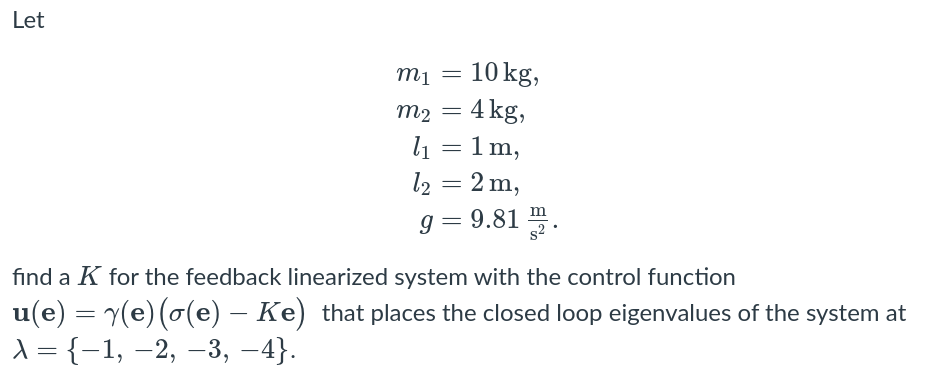

realspecs = struct("m1", 10, "m2", 4, "l1", 1, "l2", 2, "g", 9.81)

realspecs = struct with fields:
    m1: 10
    m2: 4
    l1: 1
    l2: 2
     g: 9.8100


e = [e1; e2; e3; e4;]

$$e = \left(\begin{array}{c} e_{1}\\ e_{2}\\ e_{3}\\ e_{4} \end{array}\right)$$


e_fdb = simplify(de(e, u, realspecs))

$$e\_fdb = \left(\begin{array}{c} e_{3}\\ e_{4}\\ -e_{1}\,k_{31}-e_{3}\,k_{33}\\ -e_{2}\,k_{42}-e_{4}\,k_{44} \end{array}\right)$$


A = simplify(jacobian(e_fdb,e))

$$A = \left(\begin{array}{cccc} 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ -k_{31} & 0 & -k_{33} & 0\\ 0 & -k_{42} & 0 & -k_{44} \end{array}\right)$$

simplify(eig(A))

$$ans = \left(\begin{array}{c} -\frac{k_{33}}{2}-\frac{\sqrt{{k_{33}}^{2}-4\,k_{31}}}{2}\\ \frac{\sqrt{{k_{33}}^{2}-4\,k_{31}}}{2}-\frac{k_{33}}{2}\\ -\frac{k_{44}}{2}-\frac{\sqrt{{k_{44}}^{2}-4\,k_{42}}}{2}\\ \frac{\sqrt{{k_{44}}^{2}-4\,k_{42}}}{2}-\frac{k_{44}}{2} \end{array}\right)$$

eqn = eig(A) + [4;3;2;1]

$$eqn = \left(\begin{array}{c} 4-\frac{\sqrt{{k_{33}}^{2}-4\,k_{31}}}{2}-\frac{k_{33}}{2}\\ \frac{\sqrt{{k_{33}}^{2}-4\,k_{31}}}{2}-\frac{k_{33}}{2}+3\\ 2-\frac{\sqrt{{k_{44}}^{2}-4\,k_{42}}}{2}-\frac{k_{44}}{2}\\ \frac{\sqrt{{k_{44}}^{2}-4\,k_{42}}}{2}-\frac{k_{44}}{2}+1 \end{array}\right)$$

K_ = solve(eqn, [K(3,1); K(3,3); K(4,2); K(4,4);])

K_ = struct with fields:
    k31: [1×1 sym]
    k33: [1×1 sym]
    k42: [1×1 sym]
    k44: [1×1 sym]


K_ = [K_.k31; K_.k33; K_.k42; K_.k44]

$$K\_ = \left(\begin{array}{c} 12\\ 7\\ 2\\ 3 \end{array}\right)$$

K = [ 0 0 1 0; 0 0 0 1; 12 0 7 0; 0 2 0 3;]

K =      0     0     1     0
     0     0     0     1
    12     0     7     0
     0     2     0     3



% Emulating for different xd

xd1 = [0; pi/2; 0; 0;]

xd1 =          0
    1.5708
         0
         0


xd2 = [pi/2; 0; 0; 0;]

xd2 =     1.5708
         0
         0
         0


xd3 = [pi/4; pi/4; 0; 0;]

xd3 =     0.7854
    0.7854
         0
         0



x0 = [0; 0; 0; 0;]

x0 =      0
     0
     0
     0


e0 = xd1 - x0

e0 =          0
    1.5708
         0
         0


tspan = 0:0.1:5

tspan =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000



fe = @(e, specs) -f(xd1-e, specs)

fe = function_handle with value:
    @(e,specs)-f(xd1-e,specs)


ge = @(e, specs) -g(xd1-e, specs)

ge = function_handle with value:
    @(e,specs)-g(xd1-e,specs)


gamma = @(x, specs) [ zeros(2,2) -M(x, specs)*T]

gamma = function_handle with value:
    @(x,specs)[zeros(2,2),-M(x,specs)*T]


sigma = @(e, specs) -fe(e, specs)

sigma = function_handle with value:
    @(e,specs)-fe(e,specs)


u = @(e, specs) gamma(xd1-e, specs)*(sigma(e, specs) - K*e)

u = function_handle with value:
    @(e,specs)gamma(xd1-e,specs)*(sigma(e,specs)-K*e)


de = @(e,u, specs) fe(e, specs) + ge(e, specs)*u(e, specs)

de = function_handle with value:
    @(e,u,specs)fe(e,specs)+ge(e,specs)*u(e,specs)



[t,e]=ode45(@(t,e) de(e, u, realspecs), tspan, e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =          0    1.5708         0         0
   -0.0000    1.5566   -0.0000   -0.2705
   -0.0000    1.5192   -0.0000   -0.4663
   -0.0000    1.4653   -0.0000   -0.6032
   -0.0000    1.4001   -0.0000   -0.6944
   -0.0000    1.3276    0.0000   -0.7497
   -0.0000    1.2510    0.0000   -0.7779
   -0.0000    1.1728   -0.0000   -0.7855
   -0.0000    1.0945   -0.0000   -0.7773
   -0.0000    1.0176   -0.0000   -0.7579


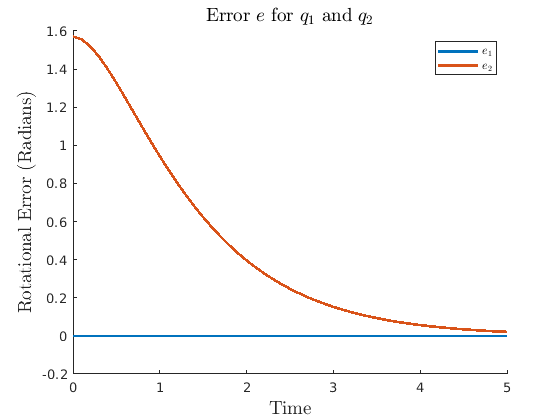

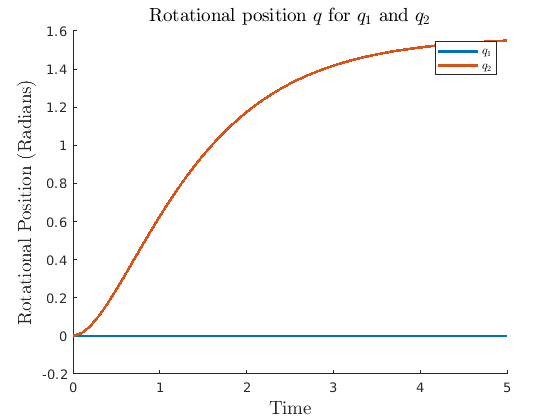


figure
title("Error $e$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Error (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, e(:,1), 'LineWidth', 2)
plot(t, e(:,2), 'LineWidth', 2)

legend(["$e_1$", "$e_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/error-c1.png','Resolution',300)

figure
title("Rotational position $q$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Position (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd1(1) - e(:,1), 'LineWidth', 2)
plot(t, xd1(2) - e(:,2), 'LineWidth', 2)

legend(["$q_1$", "$q_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-position-c1.png','Resolution',300)

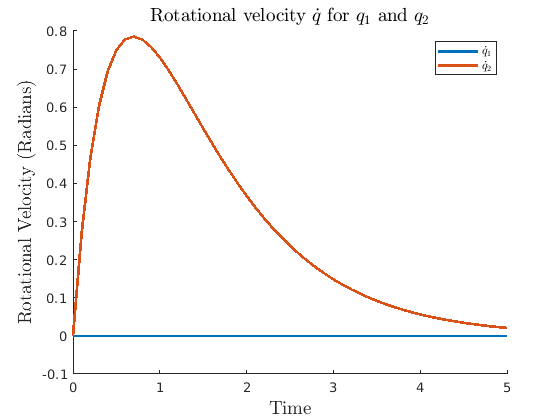


figure
title("Rotational velocity $\dot{q}$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Velocity (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd1(3) - e(:,3), 'LineWidth', 2)
plot(t, xd1(4) - e(:,4), 'LineWidth', 2)

legend(["$\dot{q}_1$", "$\dot{q}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-velocity-c1.png','Resolution',300)



e0 = xd2 - x0

e0 =     1.5708
         0
         0
         0



fe = @(e, specs) -f(xd2-e, specs)

fe = function_handle with value:
    @(e,specs)-f(xd2-e,specs)


ge = @(e, specs) -g(xd2-e, specs)

ge = function_handle with value:
    @(e,specs)-g(xd2-e,specs)


gamma = @(x, specs) [ zeros(2,2) -M(x, specs)*T]

gamma = function_handle with value:
    @(x,specs)[zeros(2,2),-M(x,specs)*T]


sigma = @(e, specs) -fe(e, specs)

sigma = function_handle with value:
    @(e,specs)-fe(e,specs)


u = @(e, specs) gamma(xd2-e, specs)*(sigma(e, specs) - K*e)

u = function_handle with value:
    @(e,specs)gamma(xd2-e,specs)*(sigma(e,specs)-K*e)


de = @(e,u, specs) fe(e, specs) + ge(e, specs)*u(e, specs)

de = function_handle with value:
    @(e,u,specs)fe(e,specs)+ge(e,specs)*u(e,specs)



[t,e]=ode45(@(t,e) de(e, u, realspecs), tspan, e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =     1.5708         0         0         0
    1.4959   -0.0000   -1.3290   -0.0000
    1.3309   -0.0000   -1.8754   -0.0000
    1.1352   -0.0000   -1.9862   -0.0000
    0.9411   -0.0000   -1.8718   -0.0000
    0.7642   -0.0000   -1.6550   -0.0000
    0.6111   -0.0000   -1.4057   -0.0000
    0.4829   -0.0000   -1.1621   -0.0000
    0.3779   -0.0000   -0.9415   -0.0000
    0.2935   -0.0000   -0.7518   -0.0000


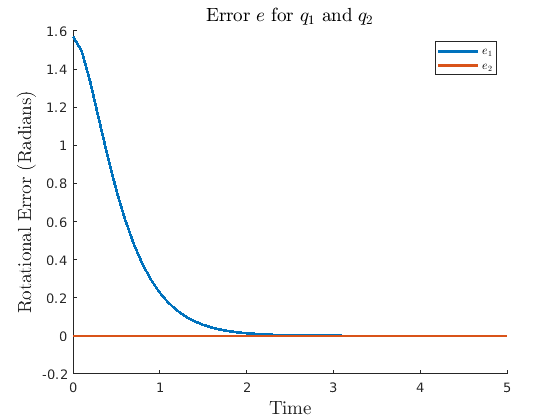


figure
title("Error $e$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Error (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, e(:,1), 'LineWidth', 2)
plot(t, e(:,2), 'LineWidth', 2)

legend(["$e_1$", "$e_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/error-c2.png','Resolution',300)

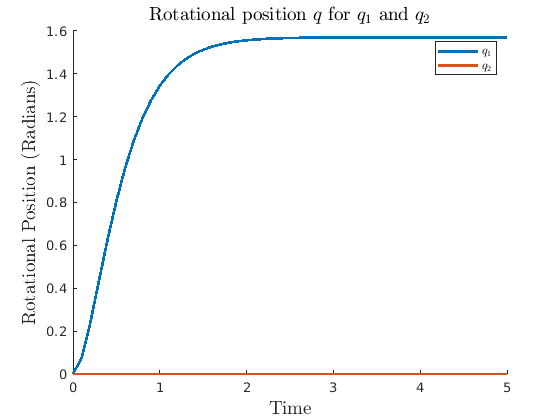


figure
title("Rotational position $q$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Position (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd2(1) - e(:,1), 'LineWidth', 2)
plot(t, xd2(2) - e(:,2), 'LineWidth', 2)

legend(["$q_1$", "$q_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-position-c2.png','Resolution',300)

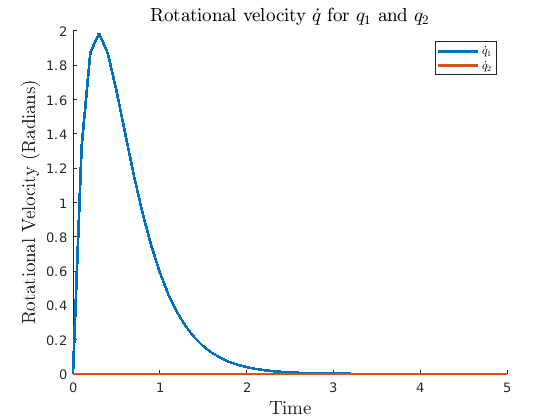


figure
title("Rotational velocity $\dot{q}$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Velocity (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd2(3) - e(:,3), 'LineWidth', 2)
plot(t, xd2(4) - e(:,4), 'LineWidth', 2)

legend(["$\dot{q}_1$", "$\dot{q}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-velocity-c2.png','Resolution',300)

e0 = xd3 - x0

e0 =     0.7854
    0.7854
         0
         0



fe = @(e, specs) -f(xd3-e, specs)

fe = function_handle with value:
    @(e,specs)-f(xd3-e,specs)


ge = @(e, specs) -g(xd3-e, specs)

ge = function_handle with value:
    @(e,specs)-g(xd3-e,specs)


gamma = @(x, specs) [ zeros(2,2) -M(x, specs)*T]

gamma = function_handle with value:
    @(x,specs)[zeros(2,2),-M(x,specs)*T]


sigma = @(e, specs) -fe(e, specs)

sigma = function_handle with value:
    @(e,specs)-fe(e,specs)


u = @(e, specs) gamma(xd3-e, specs)*(sigma(e, specs) - K*e)

u = function_handle with value:
    @(e,specs)gamma(xd3-e,specs)*(sigma(e,specs)-K*e)


de = @(e,u, specs) fe(e, specs) + ge(e, specs)*u(e, specs)

de = function_handle with value:
    @(e,u,specs)fe(e,specs)+ge(e,specs)*u(e,specs)



[t,e]=ode45(@(t,e) de(e, u, realspecs), tspan, e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =     0.7854    0.7854         0         0
    0.7480    0.7783   -0.6645   -0.1353
    0.6654    0.7596   -0.9376   -0.2331
    0.5676    0.7326   -0.9932   -0.3016
    0.4705    0.7000   -0.9359   -0.3471
    0.3821    0.6638   -0.8274   -0.3749
    0.3056    0.6255   -0.7030   -0.3890
    0.2414    0.5864   -0.5809   -0.3927
    0.1890    0.5472   -0.4709   -0.3887
    0.1467    0.5088   -0.3758   -0.3790


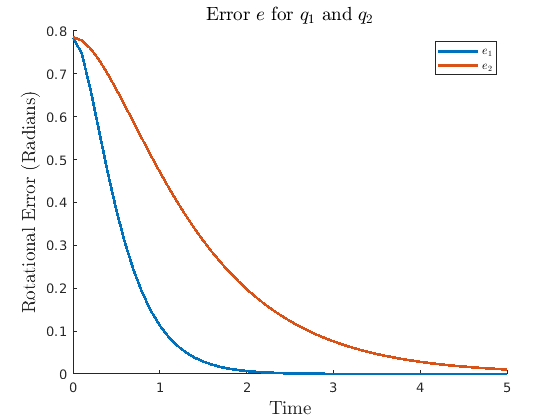


figure
title("Error $e$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Error (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, e(:,1), 'LineWidth', 2)
plot(t, e(:,2), 'LineWidth', 2)

legend(["$e_1$", "$e_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/error-c3.png','Resolution',300)

figure
title("Rotational position $q$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Position (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(1) - e(:,1), 'LineWidth', 2)
plot(t, xd3(2) - e(:,2), 'LineWidth', 2)

legend(["$q_1$", "$q_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-position-c3.png','Resolution',300)

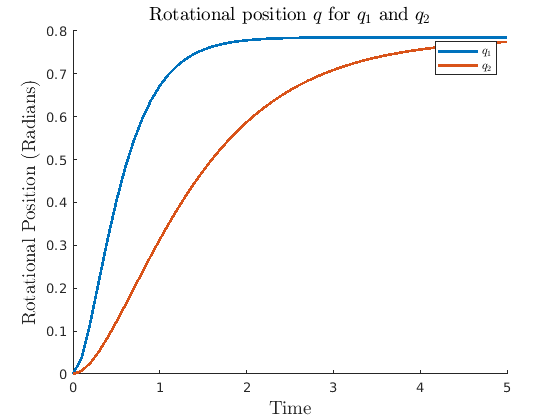

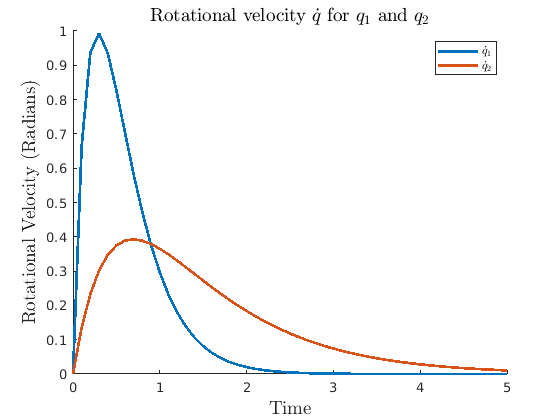


figure
title("Rotational velocity $\dot{q}$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Velocity (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(3) - e(:,3), 'LineWidth', 2)
plot(t, xd3(4) - e(:,4), 'LineWidth', 2)

legend(["$\dot{q}_1$", "$\dot{q}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-velocity-c3.png','Resolution',300)

## Part D

e0 = xd3 - x0;

limit_u = 500;

fe = @(e, specs) -f(xd3-e, specs);
ge = @(e, specs) -g(xd3-e, specs);
gamma = @(x, specs) [ zeros(2,2) -M(x, specs)*T];
sigma = @(e, specs) -fe(e, specs);
u = @(e, specs) min(max(gamma(xd3-e, specs)*(sigma(e, specs) - K*e), -limit_u), limit_u);
de = @(e,u, specs) fe(e, specs) + ge(e, specs)*u(e, specs);

[t,e]=ode45(@(t,e) de(e, u, realspecs), tspan, e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =     0.7854    0.7854         0         0
    0.8375    0.6262    1.1225   -3.3407
    1.0187    0.0951    2.3331   -7.0400
    1.1969   -0.6100    0.7895   -6.2694
    1.1955   -1.1443   -0.6505   -4.4881
    1.0927   -1.5204   -1.3098   -3.0910
    0.9482   -1.7728   -1.5254   -2.0027
    0.7954   -1.9292   -1.5019   -1.1619
    0.6517   -2.0117   -1.3622   -0.5190
    0.5245   -2.0382   -1.1763   -0.0338


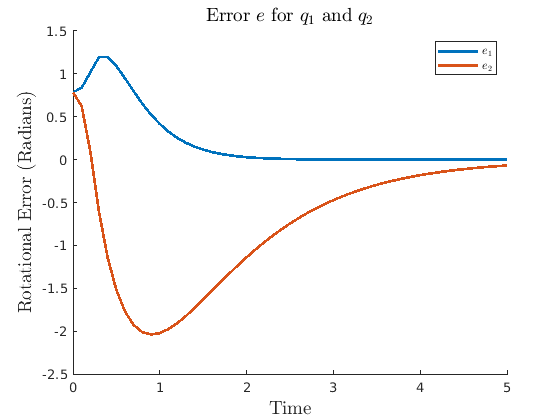


figure
title("Error $e$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Error (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, e(:,1), 'LineWidth', 2)
plot(t, e(:,2), 'LineWidth', 2)

legend(["$e_1$", "$e_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/error-d1.png','Resolution',300)

figure
title("Rotational position $q$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Position (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(1) - e(:,1), 'LineWidth', 2)
plot(t, xd3(2) - e(:,2), 'LineWidth', 2)

legend(["$q_1$", "$q_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-position-d1.png','Resolution',300)


figure
title("Rotational velocity $\dot{q}$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Velocity (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(3) - e(:,3), 'LineWidth', 2)
plot(t, xd3(4) - e(:,4), 'LineWidth', 2)

legend(["$\dot{q}_1$", "$\dot{q}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-velocity-d1.png','Resolution',300)




limit_u = 200;

fe = @(e, specs) -f(xd3-e, specs);
ge = @(e, specs) -g(xd3-e, specs);
gamma = @(x, specs) [ zeros(2,2) -M(x, specs)*T];
sigma = @(e, specs) -fe(e, specs);
u = @(e, specs) min(max(gamma(xd3-e, specs)*(sigma(e, specs) - K*e), -limit_u), limit_u);
de = @(e,u, specs) fe(e, specs) + ge(e, specs)*u(e, specs);

[t,e]=ode45(@(t,e) de(e, u, realspecs), tspan, e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =     0.7854    0.7854         0         0
    0.8841    0.5996    1.9579   -3.6863
    1.1610    0.0790    3.4162   -6.4062
    1.5313   -0.6134    3.8553   -7.2050
    1.9150   -1.3406    3.7410   -7.3160
    2.2503   -2.0678    2.6775   -7.0006
    2.4077   -2.6961    0.4934   -5.5172
    2.3729   -3.1760   -1.0818   -4.1099
    2.2002   -3.5148   -2.3245   -2.6555
    1.9438   -3.7373   -2.6601   -1.9270


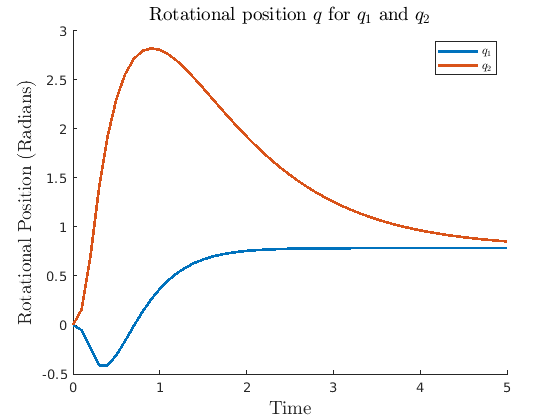

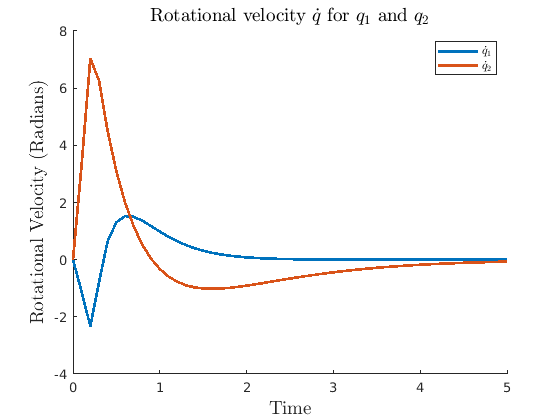

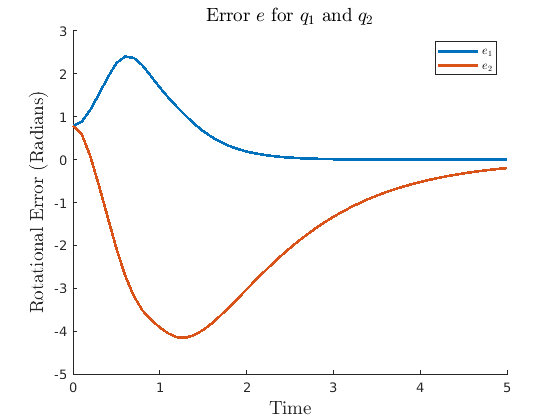


figure
title("Error $e$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Error (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, e(:,1), 'LineWidth', 2)
plot(t, e(:,2), 'LineWidth', 2)

legend(["$e_1$", "$e_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/error-d2.png','Resolution',300)

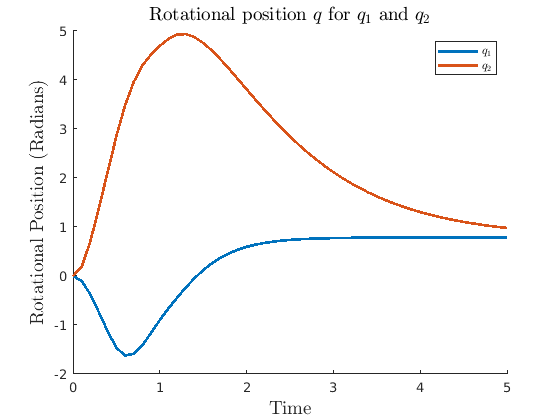


figure
title("Rotational position $q$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Position (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(1) - e(:,1), 'LineWidth', 2)
plot(t, xd3(2) - e(:,2), 'LineWidth', 2)

legend(["$q_1$", "$q_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-position-d2.png','Resolution',300)

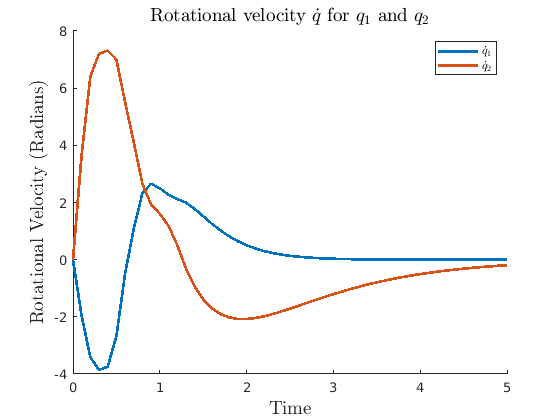


figure
title("Rotational velocity $\dot{q}$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Velocity (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(3) - e(:,3), 'LineWidth', 2)
plot(t, xd3(4) - e(:,4), 'LineWidth', 2)

legend(["$\dot{q}_1$", "$\dot{q}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-velocity-d2.png','Resolution',300)






limit_u = 75;
tspan = 0:0.1:10

tspan =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000



fe = @(e, specs) -f(xd3-e, specs);
ge = @(e, specs) -g(xd3-e, specs);
gamma = @(x, specs) [ zeros(2,2) -M(x, specs)*T];
sigma = @(e, specs) -fe(e, specs);
u = @(e, specs) min(max(gamma(xd3-e, specs)*(sigma(e, specs) - K*e), -limit_u), limit_u);
de = @(e,u, specs) fe(e, specs) + ge(e, specs)*u(e, specs);

[t,e]=ode45(@(t,e) de(e, u, realspecs), tspan, e0)

t =          0
    0.1000
    0.2000
    0.3000
    0.4000
    0.5000
    0.6000
    0.7000
    0.8000
    0.9000


e =     0.7854    0.7854         0         0
    0.8531    0.6850    1.3523   -2.0042
    1.0528    0.3912    2.6028   -3.7882
    1.3610   -0.0444    3.4880   -4.7498
    1.7381   -0.5271    4.0147   -4.7850
    2.1592   -0.9843    4.3861   -4.2975
    2.6087   -1.3770    4.5483   -3.5217
    3.0534   -1.6841    4.2580   -2.6111
    3.4421   -1.9000    3.4388   -1.7221
    3.7294   -2.0308    2.2643   -0.9069


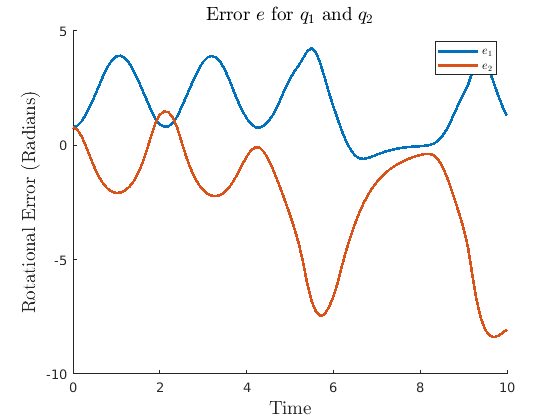


figure
title("Error $e$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Error (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, e(:,1), 'LineWidth', 2)
plot(t, e(:,2), 'LineWidth', 2)

legend(["$e_1$", "$e_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/error-d3.png','Resolution',300)

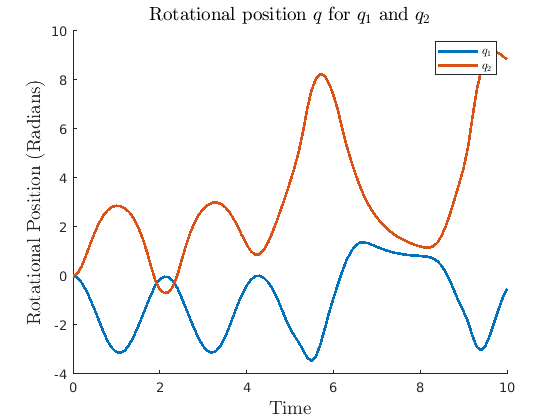


figure
title("Rotational position $q$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Position (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(1) - e(:,1), 'LineWidth', 2)
plot(t, xd3(2) - e(:,2), 'LineWidth', 2)

legend(["$q_1$", "$q_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-position-d3.png','Resolution',300)

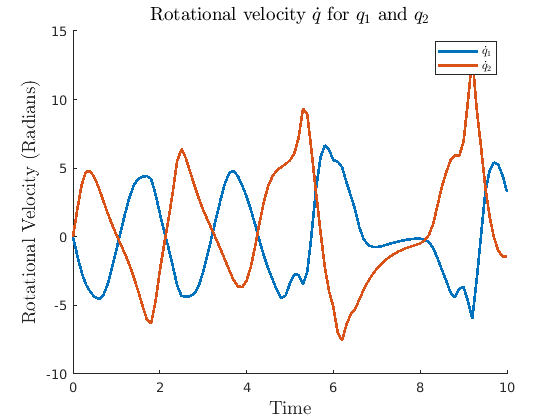


figure
title("Rotational velocity $\dot{q}$ for $q_1$ and $q_2$", 'Interpreter', 'latex', "FontSize", 14);
xlabel("Time", 'Interpreter', 'latex', "FontSize", 14);
ylabel("Rotational Velocity (Radians)", 'Interpreter', 'latex', 'Fontsize', 14)
hold on

plot(t, xd3(3) - e(:,3), 'LineWidth', 2)
plot(t, xd3(4) - e(:,4), 'LineWidth', 2)

legend(["$\dot{q}_1$", "$\dot{q}_2$"], 'Interpreter', "latex")

hold off
exportgraphics(gcf,'figures/rotational-velocity-d3.png','Resolution',300)

function output = M(x, specs)
    m1 = specs.m1;
    m2 = specs.m2;
    l1 = specs.l1;
    l2 = specs.l2;
    g = specs.g;

    q1 = x(1);
    q2 = x(2);
    q1dot = x(3);
    q2dot = x(4);
    output = [
        (m1+m2)*l1^2 + m2*l2^2 + 2*l1*l2*m2*cos(q2)     m2*l2*(l1*cos(q2) + l2);
        m2*l2*(l1*cos(q2)+l2)                           m2*l2^2
    ];
end
function output = phi(x, specs)
    m1 = specs.m1;
    m2 = specs.m2;
    l1 = specs.l1;
    l2 = specs.l2;
    g = specs.g;
    
    q1 = x(1);
    q2 = x(2);
    q1dot = x(3);
    q2dot = x(4);
    output = [
        (m1+m2)*g*l1*cos(q1) + m2*l2*(g*cos(q1+q2)-l1*q2dot*(2*q1dot+q2dot)*sin(q2))
        m2*l2*(l1*q1dot^2*sin(q2)+g*cos(q1+q2))
    ];
end
